## Image Conditioning

Note: Finally realized I could insert equations :')

### Image noise

Contaminated images with noise, which could affect the system detection of a robot. Other noises could be used to test filters performance.

Expression: $\hat{f} \left(x,y\right)=\left\lbrace \begin{array}{ll}
f\left(x,y\right) & a<l*\\
f\left(x,y\right)+\mathrm{bc} & a\ge l*
\end{array}\right.$

where:

- $a\in \left\lbrack 0,1\right\rbrack$: Random variable

- $l*\in \left\lbrack 0,1\right\rbrack$: Controls how much is $f\left(x,y\right)$ contaminated

- $c$: Controls how sever the contamination is

- $b\in \left\lbrace -1,1\right\rbrace$: Controls if noise is additive or subtractive

In case the image's pixels have a range from $\left\lbrack 0,l-1\right\rbrack$, c will range between:


$$0\le f\left(x,y\right)\pm c\le l-1$$


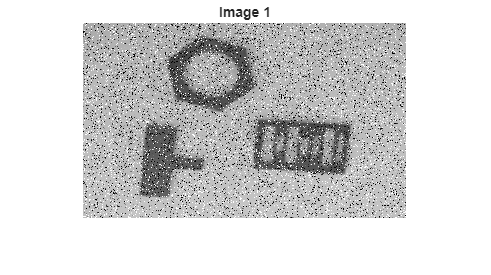

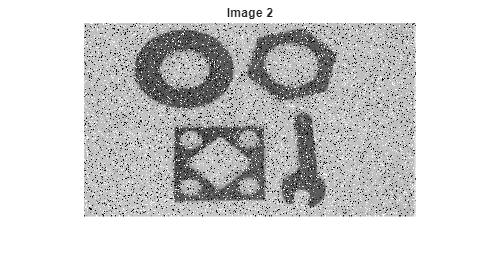

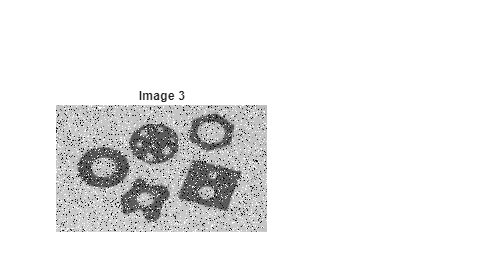

clc; clear;

for p = 1:3
    img = sprintf('images\\Cap4 img%d.png', p);
    f = imread(img);
    [n, m, t] = size(f);
    g = zeros(n, m, 1, 'uint8');
    l_star = 0.2;
    l = 255;

    for y = 1:n
        for x = 1:m
            i = f(y,x);
            a = rand;
            b = randi([0 1])*2 - 1;
            c = randi([0 l-1]);

            if a >= 1 - l_star
                g(y,x) = i + b * c;
            else
                g(y,x) = i;
            end
        end
    end

    figure;
    imshow(g);
    title(sprintf('Image %d', p));
end

If image's nature is unknown, its assume that c will follow a Gaussean behaviour like:


$$c=e^{-\frac{z^2 }{2\sigma^2 }}$$


where:

- $z\in {\mathbb{R}}_+ \cup 0$ and $\sigma \in {\mathbb{R}}_+$